clear all ; 
close all ; 
clc ; 

files = {'Data/logs_1.mat', 'Data/logs_3.mat', 'Data/logs_5.mat', ...
         'Data/logs_7.mat', 'Data/logs_9.mat', 'Data/logs_11.mat'};

load( files{1} )
G_current = oe(data , [8, 8, 1] ) ; 
G = stack( 1 , G_current ) ;

for idx = 1:length(files)
    disp(files{idx});
    load( files{idx} ) ; 
    G_current = oe(data , [8, 8, 1] ) ; 
    G = stack( 1 , G , G_current ) ; 
end

Data/logs_1.mat
Data/logs_3.mat
Data/logs_5.mat
Data/logs_7.mat
Data/logs_9.mat
Data/logs_11.mat



chosen_nominal_model = 6 ; 
nom_model = G(:,:,chosen_nominal_model,1) ; % take model 4 as the nominal model 

[B, A] = tfdata( nom_model , 'v' ) ; 
Ts = nom_model.Ts ; 

type = "poles_2" ; 

if( type == "poles_1" )
    Pideal = poly([0.8, 0.9 , 0.95, 0.1,0.3,0.3,0.3,0.3,0.2,0.1,0.2,0.2,0.1,0.1,0.1,0.1,0.1]) ;
elseif( type == "poles_2")
   Pideal = poly([0.95, 0.95 , 0.99, -0.767 ,0.1,0.1,0.2,0.2,0.1,0.1,0.1,0.1,0.1,0.1,0.1,0.1,0.1]) ; 
end

Hs = [1 , -1 ] ; 
%Hs=1;
%Hr = 1 ; 
%Hr = [1 , 1 ] ; 
Hr=[1, 1];

[R,S]=poleplace(B,A,Hr,Hs, Pideal ) ; 
Pplaced = conv(A,S)+conv(B,R) ; 

disp( Pideal )

  Columns 1 through 12

    1.0000   -3.6230    4.7814   -2.2245   -0.9319    1.7822   -1.1144    0.4223   -0.1103    0.0209   -0.0030    0.0003

  Columns 13 through 18

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000



disp( Pplaced(1:4) )

    1.0000   -3.6230    4.7814   -2.2245



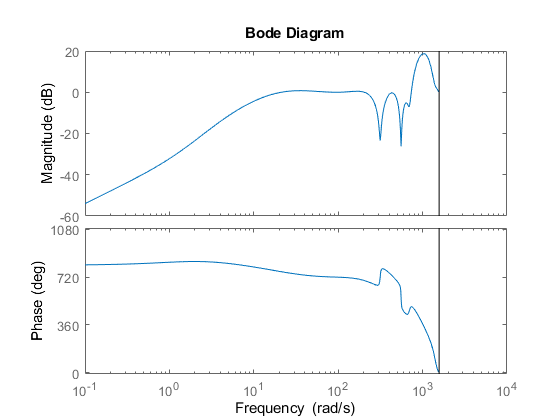



T = sum( Pplaced ) / sum( B ) ; 

%% Bode-diagram

sens=tf(conv(A,S),conv(A,S)+conv(B,R),Ts,'variable','z^-1');

sensU=tf(conv(A,R),conv(A,S)+conv(B,R),Ts,'variable','z^-1');

figure(3)
bode(sens)

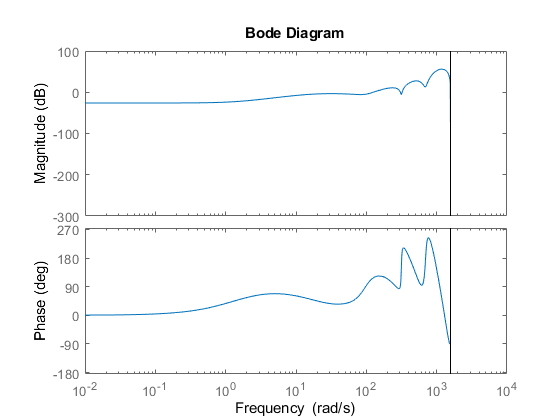


figure(4)
bode(sensU)

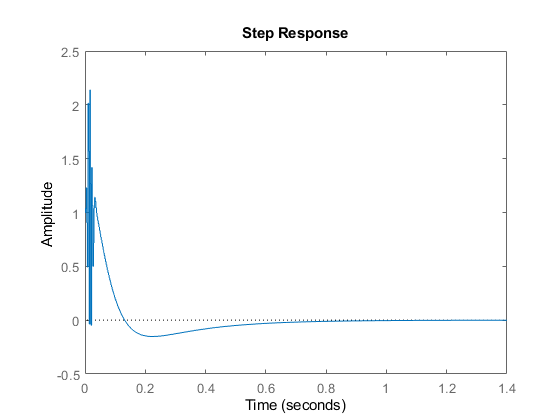

step(sens)

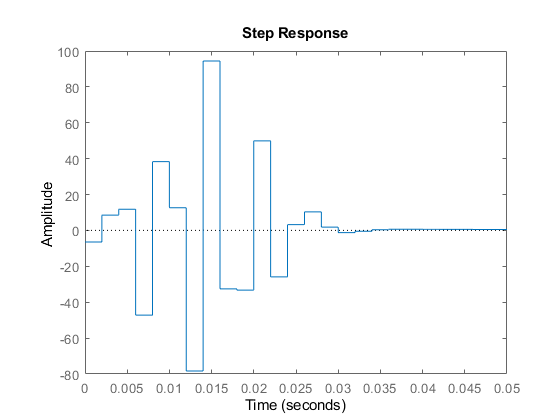

step(sensU)


Mm=1/norm(sens,inf)

Mm = 0.1189


%% Q-parametrization to complete 

s = tf('s') ; m = 0.5 ; omega_b = 10 ; 
W1s = m * (s+omega_b) / (s+1e-5) ; 
% Convert to discrete time using zero-order hold
%Ts = 0.01 ; 
W1z = c2d(W1s, Ts, 'zoh'); 

% Compute W2 in discrete time
[~, info] = ucover(G, G(:,:,chosen_nominal_model,:) , 7) ;
W2=info.W1 ; 


rng(0);
fprintf('\n') ; 
orderQinit = 10 ; %Can be changed (between 3 and 6 maybe) 
Q_init = -1 + 2*rand(1,orderQinit) 

Q_init =     0.6294    0.8116   -0.7460    0.8268    0.2647   -0.8049   -0.4430    0.0938    0.9150    0.9298




%%
options = optimoptions('fmincon', 'Display', 'iter','Algorithm', 'interior-point'); 
options.MaxFunctionEvaluations = Inf ; 
options.MaxIterations = 10000 ; 


obj = @(Q) define_objective( A ,R,Hr,Hs, Q , Pplaced , Ts ) ;
constraint_function = @(Q) constraint(Q, A, B, R, S, Hr, Hs, Pplaced, 0.5, W2, 0,Ts);

%call solver
[Q,~,~,OUTPUT] = fmincon(obj, Q_init, [], [], [], [], [], [], constraint_function, options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    6.661248e+02    3.776e+00    3.197e+01
    1      25    5.977838e+02    4.417e+00    2.463e+01    8.160e+00
    2      36    5.746760e+02    4.644e+00    2.288e+01    3.021e+00
    3      49    4.975162e+02    4.532e+00    2.035e+01    8.503e+00
    4      61    3.108167e+02    2.655e+00    1.930e+01    9.368e+00
    5      72    2.967262e+02    3.296e+00    1.396e+01    2.455e+01
    6      84    2.656997e+02    1.766e+00    2.694e+01    6.807e+00
    7      95    2.494956e+02    1.418e+00    2.375e+01    1.425e+01
    8     106    9.511674e+01    6.996e-01    1.941e+01    6.163e+00
    9     117    9.133287e+01    7.013e-01    1.902e+01    1.926e-01
   10     130    7.928452e+01    6.717e-01    3.152e+01    2.897e+00
   11     142    7.610002e+01    3.646e-01    1.168e+01    6.074e+00
   12     159    6.781808e+01    1.089e-02    1

Q_best = OUTPUT.bestfeasible;

 

%% 


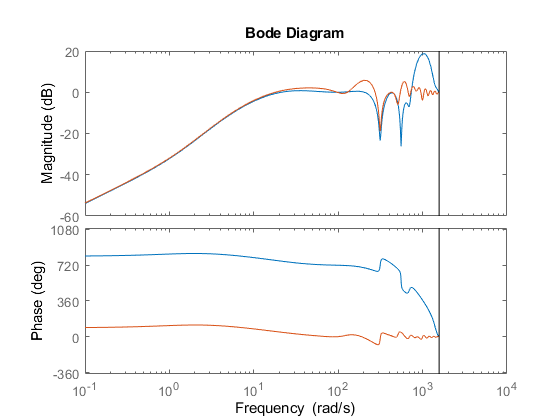

A_prime=conv(A,conv(Hr,Hs));
R_best=diff_coeff(R,-conv(A_prime,Q_best.x));
B_prime=conv(B,conv(Hr,Hs));
S_best=diff_coeff(S,conv(B_prime,Q_best.x));


sens_best=tf(conv(A,S_best),conv(A,S)+conv(B,R),Ts,'variable','z^-1');

sensU_best=tf(conv(A,R_best),conv(A,S)+conv(B,R),Ts,'variable','z^-1');

figure(3)
bode(sens,sens_best)

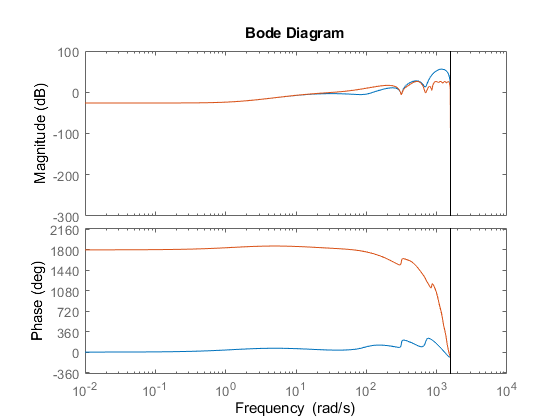


figure(4)
bode(sensU,sensU_best)

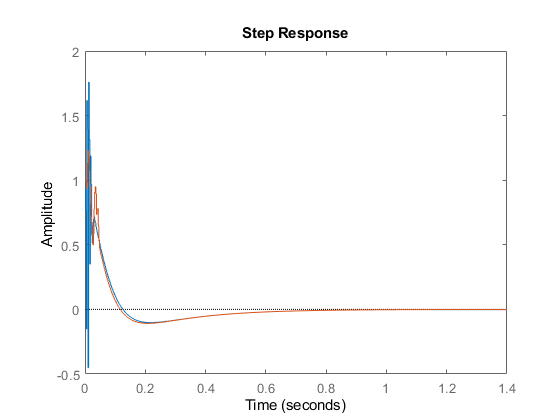



step(sens,sens_best)

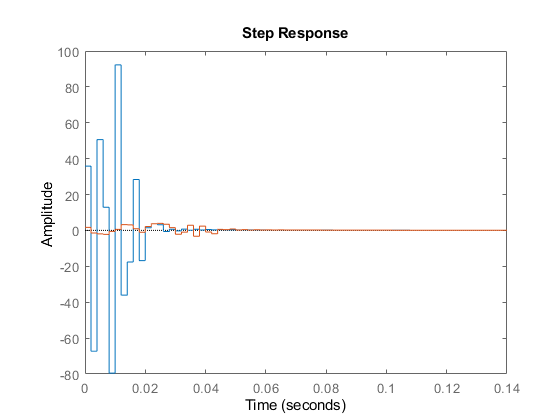

step(sensU,sensU_best)


Mm=1/norm(sens_best,inf)

Mm = 0.5116

CL = tf(conv(T,B),Pplaced,Ts,'variable','z^-1') ; 
T_best=sum(R_best);
CL_best = tf(conv(T_best,B),Pplaced,Ts,'variable','z^-1') ; 

stepinfo(CL)

ans = struct with fields:
         RiseTime: 0.4680
    TransientTime: 0.8760
     SettlingTime: 0.8760
      SettlingMin: 0.9008
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 1.6780


stepinfo(CL_best)

ans = struct with fields:
         RiseTime: 0.4680
    TransientTime: 0.8760
     SettlingTime: 0.8760
      SettlingMin: 0.9008
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 1.6780


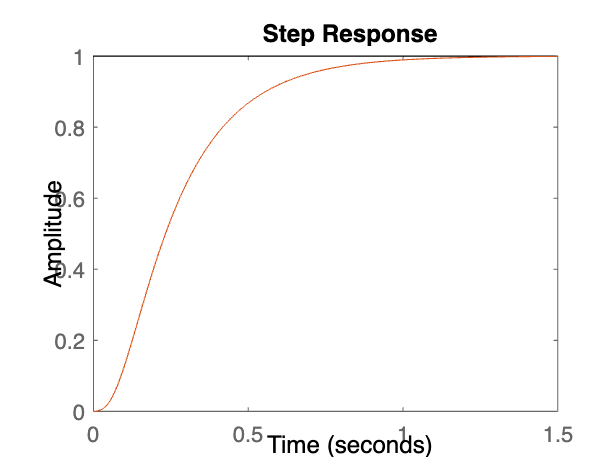

figure
step(CL,CL_best)

function obj = define_objective(A,R_0,Hr,Hs,Q,P,Ts)
    SensU = define_SensU(A,R_0,Hr,Hs, Q,P, Ts) ;
    obj = norm(SensU,Inf) ; 
end

%norm(W1*SensS,Inf) + norm(W2*(1-SensS),Inf)

function SensS = define_SensS(A,B, S_0,Hr,Hs,Q,P, Ts)
    %returns the inf norm of SensS in dB
    B_prime=conv(B,conv(Hr,Hs));
    S=diff_coeff(S_0,conv(B_prime,Q));
    num = conv(A,S) ; 
    den = P ; 
    SensS = tf(num,den,Ts, 'variable','z^-1') ;
end

function SensU = define_SensU(A,R_0,Hr,Hs, Q,P, Ts)
    %return the inf norm of SensU in dB
    A_prime=conv(A,conv(Hr,Hs));
    R=diff_coeff(R_0,-conv(A_prime,Q));
    num = conv(A,R) ; 
    den = P ; 
    SensU = tf(num,den,Ts, 'variable','z^-1') ;
end

function diff = diff_coeff(array1, array2)
    % Determine the lengths of the input arrays
    len1 = length(array1); len2 = length(array2);
    % Calculate the difference in lengths
    diff_len =abs((len1 - len2));
    
    if diff_len == 0
        diff = array1-array2 ;
    % Pad the shorter array with zeros
    elseif len1 > len2
        diff  = array1 - [array2, zeros(1, diff_len)]; 
    else
        diff = [array1, zeros(1, diff_len)] - array2; 
    end
end


function [c, ceq] = constraint(Q,A,B,R_0,S_0,Hr,Hs,P,W1,W2,W3,Ts) 
    SensS = define_SensS(A,B, S_0,Hr,Hs , Q, P , Ts);
    SensU = define_SensU(A,R_0,Hr,Hs, Q,P, Ts);
    c = [norm(W1*SensS,Inf) - 1,norm(W3*SensU,Inf) - 1];  % Inequality constraints
    %W1*S<1 & W2*T<1
    ceq = [];                                               % No equality constraints
end


